# 64 QAM modulation 

Set the simulation parameters.

clc % clears the screen
clear all % clears all variables
rng default
M = 64;                % Modulation order
k = log2(M);           % Bits per symbol
EbNoVec = (4:18)';     % Eb/No values (dB)
numSymbols = 600;     % Number of symbols to modulate

EbN0SdB=[0,1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20]; % initialise the EbN0 loop for simulation
S=1; % initialise the transmit signal power

PkNum=100; % initialise the number of packets to be transmitted



% Define RAPP PA model parameters
A0 = 1;     % Limiting output amplitude
v = 1;      % Small signal gain
p = 3;      % Smoothness parameter

Data generation 

% Generate random binary data
dataBits = randi([0 1], numSymbols * k, 1);
% Reshape the binary vector into a matrix where each row represents one symbol's bits
bit_matrix = reshape(dataBits, k, numSymbols).';
c = zeros(M, 1);  % Pre-allocate the complex constellation array

% Convert each row (symbol) to a decimal index.
% For example, [0 0 1 1] becomes 3 (since '0011' in binary equals 3).
indices = bit_matrix * (2.^(k-1:-1:0))';

QAM model 


for i = 0:M-1

    % Convert i to a binary string of fixed length.
    % dec2bin returns a character array (e.g., '0011' for i=3 with num_bits_per_symbol=4)
    binStr = dec2bin(i, k);
    % Convert the binary string to a numeric vector (0s and 1s)
    bits = binStr - '0';
        
    % For QAM, split the bits into two groups:
    %   bits(1:2:end) for the in-phase component
    %   bits(2:2:end) for the quadrature component
    pam_real = PAM_GRAY(bits(1:2:end));
    pam_imag = PAM_GRAY(bits(2:2:end));
        
    % Combine the two PAM components to form the QAM symbol
    c(i+1) = pam_real + 1i * pam_imag;
end

%Normalization
n = k / 2;
% Generate odd numbers: For n bits, these are 1, 3, ..., 2^n - 1.
odd_numbers = 1:2:(2^n - 1);
% Compute the variance factor (closed-form normalization factor):
qam_var = 1 / (2^(n-2)) * sum(odd_numbers.^2);
c = c / sqrt(qam_var);
disp(c)

   0.4629 + 0.4629i
   0.4629 + 0.1543i
   0.1543 + 0.4629i
   0.1543 + 0.1543i
   0.4629 + 0.7715i
   0.4629 + 1.0801i
   0.1543 + 0.7715i
   0.1543 + 1.0801i
   0.7715 + 0.4629i
   0.7715 + 0.1543i
   1.0801 + 0.4629i
   1.0801 + 0.1543i
   0.7715 + 0.7715i
   0.7715 + 1.0801i
   1.0801 + 0.7715i
   1.0801 + 1.0801i
   0.4629 - 0.4629i
   0.4629 - 0.1543i
   0.1543 - 0.4629i
   0.1543 - 0.1543i
   0.4629 - 0.7715i
   0.4629 - 1.0801i
   0.1543 - 0.7715i
   0.1543 - 1.0801i
   0.7715 - 0.4629i
   0.7715 - 0.1543i
   1.0801 - 0.4629i
   1.0801 - 0.1543i
   0.7715 - 0.7715i
   0.7715 - 1.0801i
   1.0801 - 0.7715i
   1.0801 - 1.0801i
  -0.4629 + 0.4629i
  -0.4629 + 0.1543i
  -0.1543 + 0.4629i
  -0.1543 + 0.1543i
  -0.4629 + 0.7715i
  -0.4629 + 1.0801i
  -0.1543 + 0.7715i
  -0.1543 + 1.0801i
  -0.7715 + 0.4629i
  -0.7715 + 0.1543i
  -1.0801 + 0.4629i
  -1.0801 + 0.1543i
  -0.7715 + 0.7715i
  -0.7715 + 1.0801i
  -1.0801 + 0.7715i
  -1.0801 + 1.0801i
  -0.4629 - 0.4629i
  -0.4629 - 0.1543i


Symbol mapping 

% Map each symbol index to its corresponding QAM constellation point.
% Since MATLAB indexing starts at 1, add 1 to the decimal index.
modulated_signal = c(indices + 1);

Constellation plot 

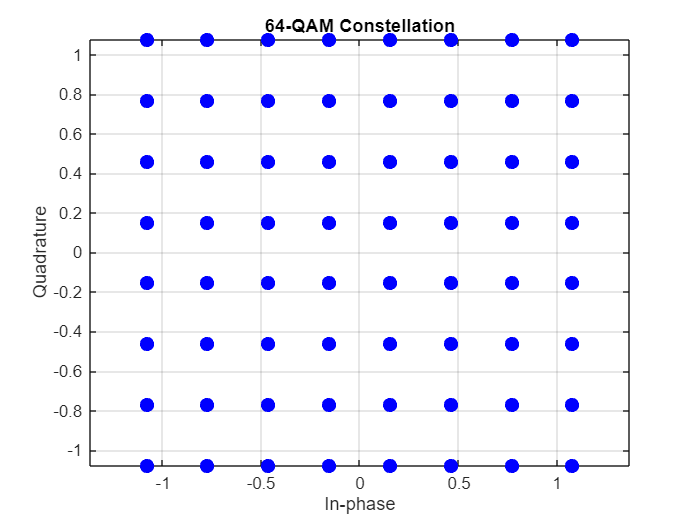

figure;
plot(real(c), imag(c), 'bo', 'MarkerFaceColor','b', 'MarkerSize',8);
grid on;
xlabel('In-phase');
ylabel('Quadrature');
title('64-QAM Constellation');
axis equal;

Modulated signal plot 

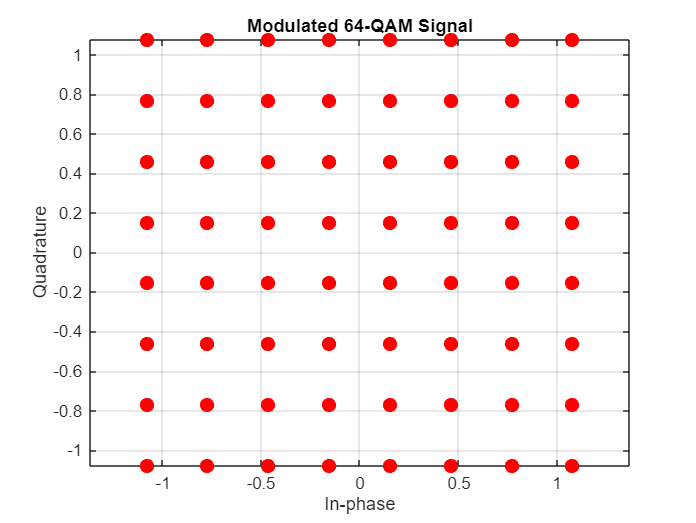

figure;
plot(real(modulated_signal), imag(modulated_signal), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
grid on;
xlabel('In-phase');
ylabel('Quadrature');
title('Modulated 64-QAM Signal');
axis equal;

Demodulation 

%% Demodulation: Minimum Distance Decision
% Pre-allocate vector for detected symbol indices
detected_indices = zeros(numSymbols,1);

% Loop over each received symbol
for n = 1:numSymbols
    % Compute squared Euclidean distances to all constellation points:
    distances = abs(modulated_signal(n) - c).^2;
    % Find the index (MATLAB indexing: 1...M) of the minimum distance:
    [~, minIdx] = min(distances);
    % To be consistent with your modulation where indices started at 0,
    % we subtract 1:
    detected_indices(n) = minIdx - 1;
end

%% Map Detected Symbol Indices Back to Bits
% Pre-allocate bit vector for the demodulated bits:
demod_bits = zeros(numSymbols*k, 1);

for n = 1:numSymbols
    % Convert the detected index to a binary string of length k
    binStr = dec2bin(detected_indices(n), k);
    % Convert the string to a numeric vector (0s and 1s)
    bits = binStr - '0';
    % Place these bits in the appropriate location of the output vector
    demod_bits((n-1)*k + 1 : n*k) = bits;
end


BER/BLER calculation 

numErrors = sum(demod_bits ~= dataBits);
BER = numErrors / length(dataBits);

**System with the AWGN channel **

% EbN0 loop
for EbN0SIndex=1:length(EbN0SdB)

    % Loop derived parameters
    EbN0S=10^(EbN0SdB(EbN0SIndex)/10); % set EbN0 value for simulation
    StDev=sqrt(S/EbN0S); % set the noise standard deviation for calibration
    % Calculate noise variance per dimension for a complex baseband signal
    % Eb/N0 (linear) is EbN0S, k is bits per symbol, and Es=1 is assumed.
    sigma = sqrt(1/(2*k*EbN0S));  % standard deviation per real dimension
    
    for PkIndex=1:PkNum
        % Generate random binary data
        dataBits = randi([0 1], numSymbols * k, 1);
        % Reshape the binary vector into a matrix where each row represents one symbol's bits
        bit_matrix = reshape(dataBits, k, numSymbols).';
        c = zeros(M, 1);  % Pre-allocate the complex constellation array
        
        % Convert each row (symbol) to a decimal index.
        % For example, [0 0 1 1] becomes 3 (since '0011' in binary equals 3).
        indices = bit_matrix * (2.^(k-1:-1:0))';
        %%% QAM Model %%% 
        for i = 0:M-1
        
            % Convert i to a binary string of fixed length.
            % dec2bin returns a character array (e.g., '0011' for i=3 with num_bits_per_symbol=4)
            binStr = dec2bin(i, k);
            % Convert the binary string to a numeric vector (0s and 1s)
            bits = binStr - '0';
                
            % For QAM, split the bits into two groups:
            %   bits(1:2:end) for the in-phase component
            %   bits(2:2:end) for the quadrature component
            pam_real = PAM_GRAY(bits(1:2:end));
            pam_imag = PAM_GRAY(bits(2:2:end));
                
            % Combine the two PAM components to form the QAM symbol
            c(i+1) = pam_real + 1i * pam_imag;
        end
        %can be simplified 

        %c = c*1/sqrt(42)
        %Normalization
        n = k / 2;
        % Generate odd numbers: For n bits, these are 1, 3, ..., 2^n - 1.
        odd_numbers = 1:2:(2^n - 1);
        % Compute the variance factor (closed-form normalization factor):
        qam_var = 1 / (2^(n-2)) * sum(odd_numbers.^2);
        c = c / sqrt(qam_var);
    
        % Map each symbol index to its corresponding QAM constellation point.
        % Since MATLAB indexing starts at 1, add 1 to the decimal index.
        modulated_signal = c(indices + 1);
        
        %RAPP model addition 
        modulated_signal_amp = abs(modulated_signal);
        modulated_signal_phs = angle(modulated_signal);
        modulated_signal_PA = RAPP_PA(modulated_signal_amp, A0, v, p);
        modulated_signal_RAPP = modulated_signal_PA .* exp(1j * modulated_signal_phs); % Recombine
        
        % Compute average power of RAPP-modified signal
        avgPower_RAPP = mean(abs(modulated_signal_RAPP).^2);

        % Scale so that the average power is 1 (or equal to the ideal modulated signal)
        modulated_signal_RAPP = modulated_signal_RAPP / sqrt(avgPower_RAPP);
        
        % Complex baseband noise vector
        noise1=StDev*(randn(numSymbols,1)+1i*randn(numSymbols,1))/sqrt(2);
        
        % Generate complex AWGN noise vector
        noise = sigma * (randn(numSymbols,1) + 1i*randn(numSymbols,1));
        
        % Received signal vector
        h=1;
        %         h=(randn+1i*randn);
        RxSymbols=h*modulated_signal+ noise; % add noise to transmit signal
        
        RxSymbolsRAPP = h*modulated_signal_RAPP+ noise;

        %% Demodulation: Minimum Distance Decision
        % Pre-allocate vector for detected symbol indices
        detected_indices = zeros(numSymbols,1);
        
        % Loop over each received symbol
        for n = 1:numSymbols
            % Compute squared Euclidean distances to all constellation points:
            distances = abs(RxSymbols(n) - c).^2;
            % Find the index (MATLAB indexing: 1...M) of the minimum distance:
            [~, minIdx] = min(distances);
            % To be consistent with your modulation where indices started at 0,
            % we subtract 1:
            detected_indices(n) = minIdx - 1;
        end
        detected_indicesRapp=zeros(numSymbols,1);
        for n = 1:numSymbols
            % Compute squared Euclidean distances to all constellation points:
            distancesRAPP = abs(RxSymbolsRAPP(n) - c).^2;
            % Find the index (MATLAB indexing: 1...M) of the minimum distance:
            [~, minIdx] = min(distancesRAPP);
            % To be consistent with your modulation where indices started at 0,
            % we subtract 1:
            detected_indicesRapp(n) = minIdx - 1;
        end
        
        %% Map Detected Symbol Indices Back to Bits
        % Pre-allocate bit vector for the demodulated bits:
        demod_bits = zeros(numSymbols*k, 1);
        demod_bitsRapp = zeros(numSymbols*k, 1);

        for n = 1:numSymbols
            % Convert the detected index to a binary string of length k
            binStr = dec2bin(detected_indices(n), k);
            % Convert the string to a numeric vector (0s and 1s)
            bits = binStr - '0';
            % Place these bits in the appropriate location of the output vector
            demod_bits((n-1)*k + 1 : n*k) = bits;
        end
        
        for n = 1:numSymbols
            % Convert the detected index to a binary string of length k
            binStr = dec2bin(detected_indicesRapp(n), k);
            % Convert the string to a numeric vector (0s and 1s)
            bits = binStr - '0';
            % Place these bits in the appropriate location of the output vector
            demod_bitsRapp((n-1)*k + 1 : n*k) = bits;
        end
        BERerrors(PkIndex) = sum(demod_bits ~= dataBits);
        %BERerrors(PkIndex) = numErrors / length(dataBits);
        BLERErrors(PkIndex)=BERerrors(PkIndex)>0; %BLER
        
        BERerrorsRapp(PkIndex) = sum(demod_bitsRapp ~= dataBits);
        %BERerrors(PkIndex) = numErrors / length(dataBits);
        BLERErrorsRapp(PkIndex)=BERerrorsRapp(PkIndex)>0; %BLER
    end
    BER(EbN0SIndex)=sum(BERerrors)/ (PkNum*length(dataBits));
    BLER(EbN0SIndex)=sum(BLERErrors)/PkNum;

    BERRapp(EbN0SIndex)=sum(BERerrorsRapp)/ (PkNum*length(dataBits));
    BLERRapp(EbN0SIndex)=sum(BLERErrorsRapp)/PkNum;
end


BER/BLER plot

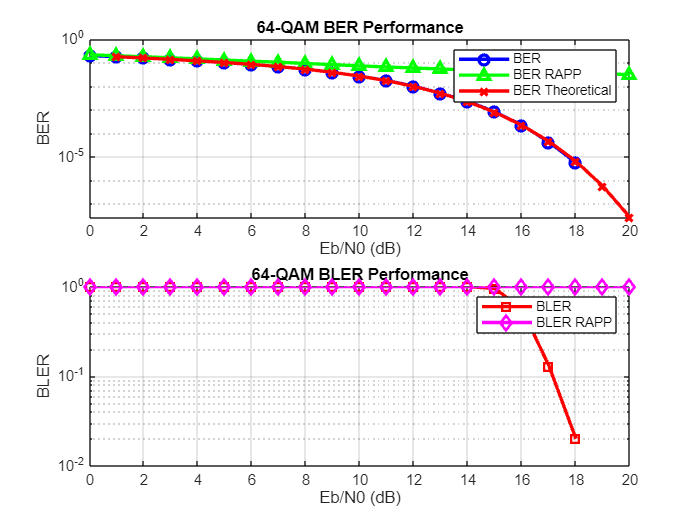

%figure('Visible','on');
%theory
SNR_min = 1;
SNR_step = 1;
SNR_max = 20;


SNR_plot = SNR_min : SNR_step : SNR_max;

[BER_theory , SER_theory] = berawgn(SNR_plot , 'QAM' , M);

figure;

% Top subplot: BER and BERRapp
subplot(2,1,1);
semilogy(EbN0SdB, BER, 'b-o', 'LineWidth', 2); hold on;
semilogy(EbN0SdB, BERRapp, 'g-^', 'LineWidth', 2); hold on;
semilogy(SNR_plot , BER_theory,'r-x','LineWidth', 2);
grid on;
xlabel('Eb/N0 (dB)');
ylabel('BER');
legend('BER', 'BER RAPP','BER Theoretical');
title('64-QAM BER Performance');

% Bottom subplot: BLER and BLERRapp
subplot(2,1,2);
semilogy(EbN0SdB, BLER, 'r-s', 'LineWidth', 2); hold on;
semilogy(EbN0SdB, BLERRapp, 'm-d', 'LineWidth', 2);
grid on;
xlabel('Eb/N0 (dB)');
ylabel('BLER');
legend('BLER', 'BLER RAPP');
title('64-QAM BLER Performance');


drawnow;


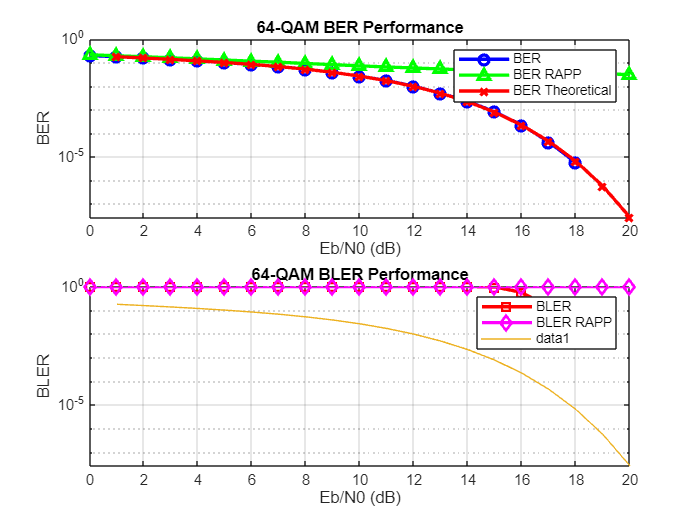

SNR_min = 1;
SNR_step = 1;
SNR_max = 20;
mod_size = 64;

SNR_plot = SNR_min : SNR_step : SNR_max;

%SER theory
[BER_theory , SER_theory] = berawgn(SNR_plot , 'QAM' , mod_size);
semilogy(SNR_plot , BER_theory)
hold on